clc; clear all; close all; 
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

RGB = imread(string(fullfile(img_path, T{336,1})));
Ig=rgb2gray(RGB);

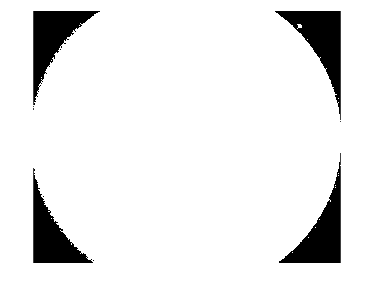

thres=Ig>8;
se = strel('disk',50);
thres_eroded=imerode(thres,se);
contour=thres-thres_eroded;
figure;
imshow(thres);

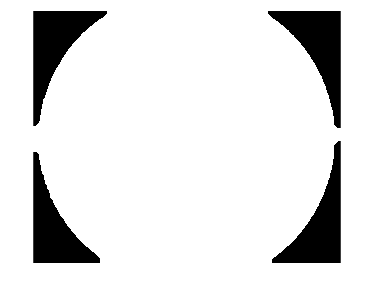

figure;
imshow(thres_eroded);

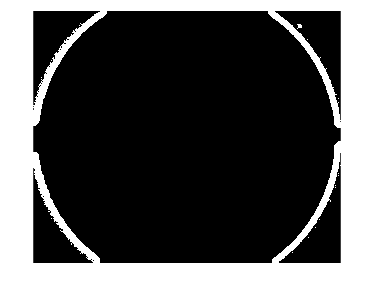

figure;
imshow(contour);

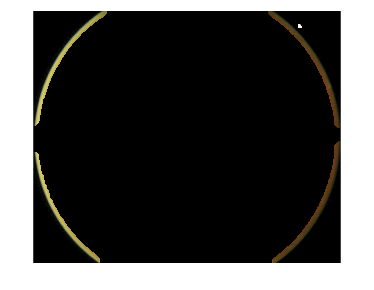

RGB=double(RGB);
plantilla=RGB.*contour;
plantilla=uint8(plantilla);
figure;
imshow(plantilla);

%cuento el número de píxeles coloreados que hay en la plantilla (porque
%puede cambiar segun la foto)
elementosNoCero = nonzeros(plantilla);

% Sumar los elementos no cero
suma = sum(elementosNoCero);

% Calcular la media de los elementos no cero
media = mean(elementosNoCero);